addpath("/Users/penquin/Library/CloudStorage/OneDrive-KMITL/Project/function");
EmiPMs = ipOpa("/Users/penquin/Library/CloudStorage/OneDrive-KMITL/Project/DataBase/EmiPMs.xlsx", "Opacity", [3, Inf])

EmiPMs = 16×6 table
    Condition1    VarName7     B7      B7CeO2_300DOCPt_300PDPF      B10       B100  
    __________    ________    _____    _______________________    _______    _______

       1500          84        3.26              ""                2.3922          0
       1500         112        5.97              ""                2.6529          0
       1500         140         8.6              ""                5.5842    0.90149
       1500         160       12.62              ""                 8.571     1.4642
       2000          84         3.7              ""               0.73846          0
       2000         112        5.04              ""                1.0324          0
       2000         140        5.04              ""                2.0049          0
       200

EmiPMs = removevars(EmiPMs, ["B7CeO2_300DOCPt_300PDPF" "B10"]);
EmiPMs(13 : end, :) = [];
EmiPMs.Properties.VariableNames = ["RPM" "Torque" "B7" "B100"] 

EmiPMs = 12×4 table
    RPM     Torque     B7       B100  
    ____    ______    _____    _______

    1500      84       3.26          0
    1500     112       5.97          0
    1500     140        8.6    0.90149
    1500     160      12.62     1.4642
    2000      84        3.7          0
    2000     112       5.04          0
    2000     140       5.04          0
    2000     160       6.61          0
    2500      84       3.38          0
    2500     112        4.2          0
    2500     140       4.46          0
    2500     160       6.18    0.11364


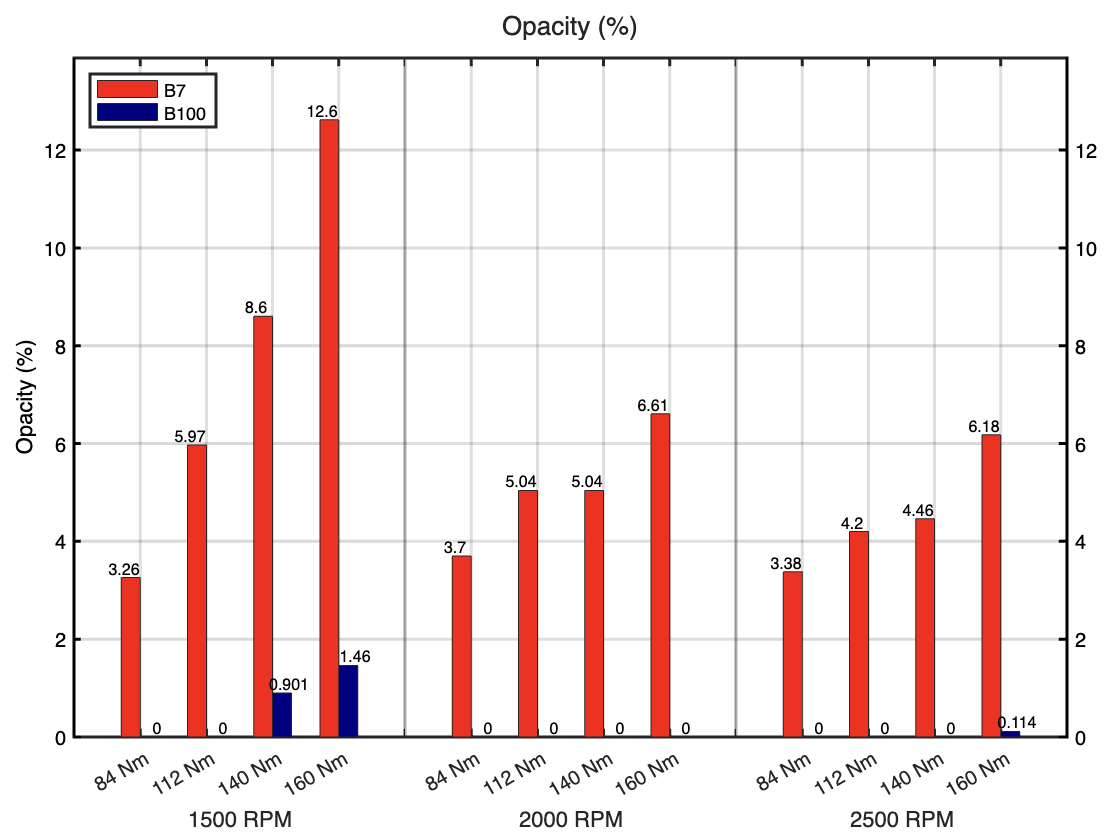

tile = ft_bar(EmiPMs, "Opacity (%)");